Open it as live script!!!

Load Indian Pines data and create a HSI(Hyperspectral Image) object.

We also show the three-band composite color image.

clear;
load('Data\Indian_pines.mat');
h = HSI(indian_pines);

% frgb = h.him(:, :, [10, 100, 170]);
% frgb = (frgb - min(frgb, [], [1, 2])) ./ ...
%     (max(frgb, [], [1, 2]) - min(frgb, [], [1, 2]));
% imshow(frgb);

MNF test in this experiment.

y_MNF = MNF(h);

Use .result_reshape() to reshape the 1D results to 2D images.

m = h.shape(1);
n = h.shape(2);
l = h.shape(3);
im_MNF = zeros(m,n,l);
for i = 1:l
    im_MNF(:,:,i) = result_reshape(h, y_MNF(:,i));
end

Imshow the first result.

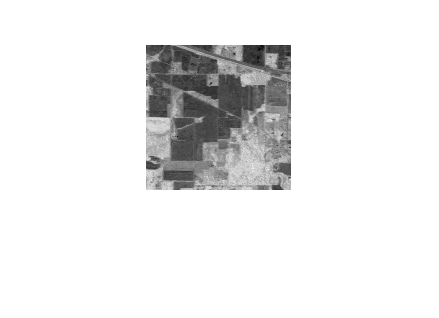

imshow(mat2gray(im_MNF(:,:,1)));